# SPECTER Planar Dynamics Model

clear
clc
close all

## Initial Conditions

x0 = 0;
z0 = 0;
vx0 = 0;
vz0 = 0;
theta0 = 0;
omega0 = 0;

X0 = [x0;
    z0;
    vx0;
    vz0;
    theta0;
    omega0];

## Parameters

p.m = 10;
p.g = 9.80665;
p.l = 0.3;
p.I = 0.5;
p.delta = deg2rad(5);

p.thrustTime = [0 0.1 0.3 1.0 1.8 2.0];
p.thrustData = [0 150 220 210 180 0];
p.tb = p.thrustTime(end);

## Dynamics Function Check

dX_test = SpecterDynamicsPlanar(0,X0,p)

dX_test =          0
         0
         0
   -9.8066
         0
         0


## Simulation

tfinal = 2;

dynamics = @(t,X) SpecterDynamicsPlanar(t,X,p);
solverOptions = odeset('RelTol',1e-9,'AbsTol',1e-11);
[t,X] = ode45(dynamics,[0,tfinal],X0,solverOptions);

## State Histories

x = X(:,1);
z = X(:,2);

vx = X(:,3);
vz = X(:,4);

theta = X(:,5);
omega = X(:,6);


## Initial Verification

fprintf('\n--- PLANAR MODEL INITIAL CHECK ---\n\n');


--- PLANAR MODEL INITIAL CHECK ---




fprintf('Final horizontal position: %.6f m\n',x(end));

Final horizontal position: 10.117488 m


fprintf('Final altitude: %.6f m\n',z(end));

Final altitude: -9.830426 m



fprintf('Final horizontal velocity: %.6f m/s\n',vx(end));

Final horizontal velocity: 5.960413 m/s


fprintf('Final vertical velocity: %.6f m/s\n',vz(end));

Final vertical velocity: -14.885639 m/s



fprintf('Final pitch angle: %.6f deg\n',rad2deg(theta(end)));

Final pitch angle: 1144.695808 deg


fprintf('Final pitch rate: %.6f deg/s\n',rad2deg(omega(end)));

Final pitch rate: 1105.595478 deg/s


## Thrust Model Verification

T0 = ThrustModelPlanar(0,p);
T01 = ThrustModelPlanar(0.1,p);
T03 = ThrustModelPlanar(0.3,p);
T10 = ThrustModelPlanar(1.0,p);
T18 = ThrustModelPlanar(1.8,p);
T20 = ThrustModelPlanar(2.0,p);
T25 = ThrustModelPlanar(2.5,p);

fprintf('\n--- THRUST MODEL VERIFICATION ---\n\n');


--- THRUST MODEL VERIFICATION ---




fprintf('T(0.0) = %.3f N\n',T0);

T(0.0) = 0.000 N


fprintf('T(0.1) = %.3f N\n',T01);

T(0.1) = 150.000 N


fprintf('T(0.3) = %.3f N\n',T03);

T(0.3) = 220.000 N


fprintf('T(1.0) = %.3f N\n',T10);

T(1.0) = 210.000 N


fprintf('T(1.8) = %.3f N\n',T18);

T(1.8) = 180.000 N


fprintf('T(2.0) = %.3f N\n',T20);

T(2.0) = 0.000 N


fprintf('T(2.5) = %.3f N\n',T25);

T(2.5) = 0.000 N


## Variable Thrust Dynamics Check

t_test = 0.3;

dX_test_03 = SpecterDynamicsPlanar(t_test,X0,p);

fprintf('\n--- DYNAMICS CHECK AT t = 0.3 s ---\n\n');


--- DYNAMICS CHECK AT t = 0.3 s ---




fprintf('xdot:     %.6f m/s\n',dX_test_03(1));

xdot:     0.000000 m/s


fprintf('zdot:     %.6f m/s\n',dX_test_03(2));

zdot:     0.000000 m/s


fprintf('ax:       %.6f m/s^2\n',dX_test_03(3));

ax:       1.917426 m/s^2


fprintf('az:       %.6f m/s^2\n',dX_test_03(4));

az:       12.109633 m/s^2


fprintf('thetadot: %.6f rad/s\n',dX_test_03(5));

thetadot: 0.000000 rad/s


fprintf('alpha:    %.6f rad/s^2\n',dX_test_03(6));

alpha:    11.504558 rad/s^2


## Variable Thrust Rotational Verification

impulse = trapz(p.thrustTime,p.thrustData);

omega_exact_final = omega0 + ...
    (p.l*sin(p.delta)/p.I)*impulse;

omega_numerical_final = omega(end);

omega_final_error = abs(omega_numerical_final - omega_exact_final);

fprintf('\n--- VARIABLE THRUST ROTATIONAL VERIFICATION ---\n\n');


--- VARIABLE THRUST ROTATIONAL VERIFICATION ---




fprintf('Total impulse: %.6f N*s\n',impulse);

Total impulse: 369.000000 N*s


fprintf('Analytical final omega: %.12f rad/s\n',omega_exact_final);

Analytical final omega: 19.296281444332 rad/s


fprintf('ODE45 final omega: %.12f rad/s\n',omega_numerical_final);

ODE45 final omega: 19.296281286678 rad/s


fprintf('Final omega error: %.12e rad/s\n',omega_final_error);

Final omega error: 1.576530621605e-07 rad/s


## Plots

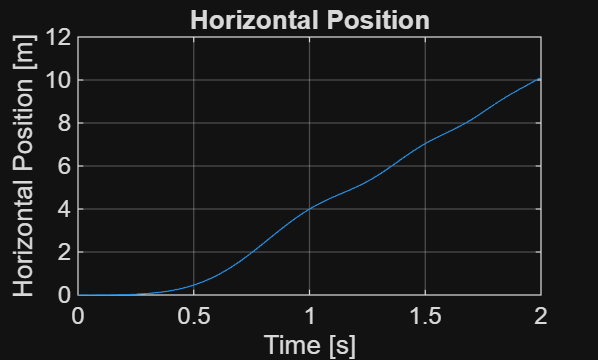

figure
plot(t,x)
xlabel('Time [s]')
ylabel('Horizontal Position [m]')
title('Horizontal Position')
grid on

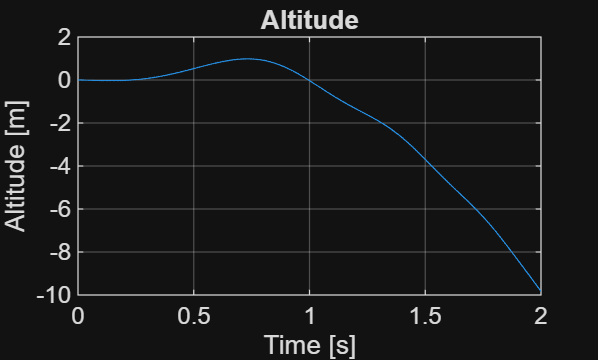


figure
plot(t,z)
xlabel('Time [s]')
ylabel('Altitude [m]')
title('Altitude')
grid on

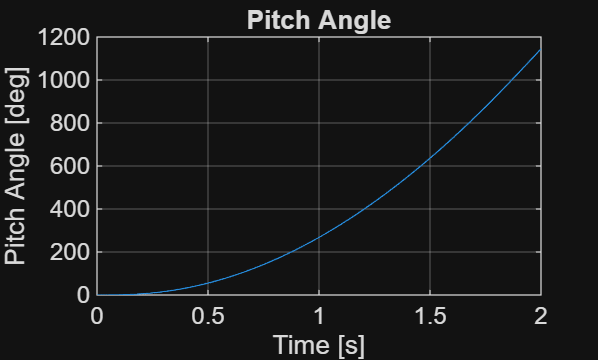


figure
plot(t,rad2deg(theta))
xlabel('Time [s]')
ylabel('Pitch Angle [deg]')
title('Pitch Angle')
grid on

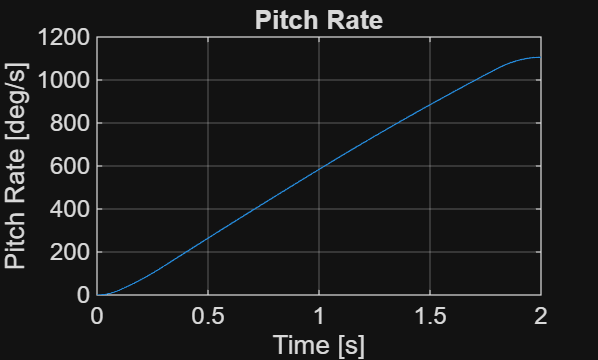


figure
plot(t,rad2deg(omega))
xlabel('Time [s]')
ylabel('Pitch Rate [deg/s]')
title('Pitch Rate')
grid on

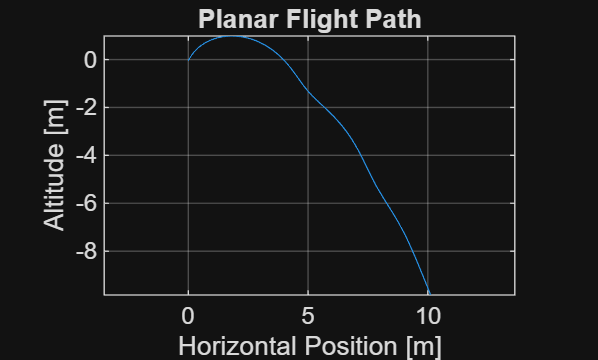


figure
plot(x,z)
xlabel('Horizontal Position [m]')
ylabel('Altitude [m]')
title('Planar Flight Path')
grid on
axis equal